# Generating PDM Wavetable Samples

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

## **1   PDM Characteristic Curve**

### 1.1   Piecewise Linear Function

fprintf('1.1 Piecewise Linear Function\n');

1.1 Piecewise Linear Function


As explained in Section "Phase Distortion Modulation" in the report, the phase distortion characteristic curve consists of two straigt sections

    $f_1(\varphi)=a\varphi$,        $0\leq\varphi\leq\varphi_0$,    running through the points $(0,0)$ and $(\varphi_0,\pi)$ and

    $f_2(\varphi) = b\varphi+c$,  $\varphi_0\leq \varphi\leq 2\pi$,  running through the points $(\varphi_0,\pi)$ and $(2\pi,2\pi)$.

Taking the slope $a$ of the first section as a variable parameter with $a\geq 1$, we can compute $\varphi_0$, $b$, and $c$.

syms a b c phi phi0 real;
assume(a>=0);
eqns = [           ...
  a*phi0   == pi,  ...
  b*phi0+c == pi,  ...
  b*2*pi+c == 2*pi ...
];
S = solve(eqns,[phi0,b,c]);
phi0 = simplify(S.phi0); fprintf('  phi0 ='); disp(phi0);

  phi0 =

$$\frac{\pi }{a}$$

b    = simplify(S.b);    fprintf('  b ='   ); disp(b);

  b =

$$\frac{a}{2\,a-1}$$

c    = simplify(S.c);    fprintf('  c ='   ); disp(c);

  c =

$$\frac{2\,\pi \,\left(a-1\right)}{2\,a-1}$$

Hence, the phase distortion modulation characteristics curve is

    
$$\varphi_{\text{PD}}(\varphi) = \begin{cases}
  a\varphi &\text{for } 0\leq\varphi<\frac{\pi}{a}\\
  \frac{a\varphi+2\pi(a-1)}{2a-1} &\text{for }\frac{\pi}{a}\leq\varphi<2\pi.
\end{cases}$$


This characteristic is implemented by the function `phipd=PDMcc(phi,a)` in the appendix below.

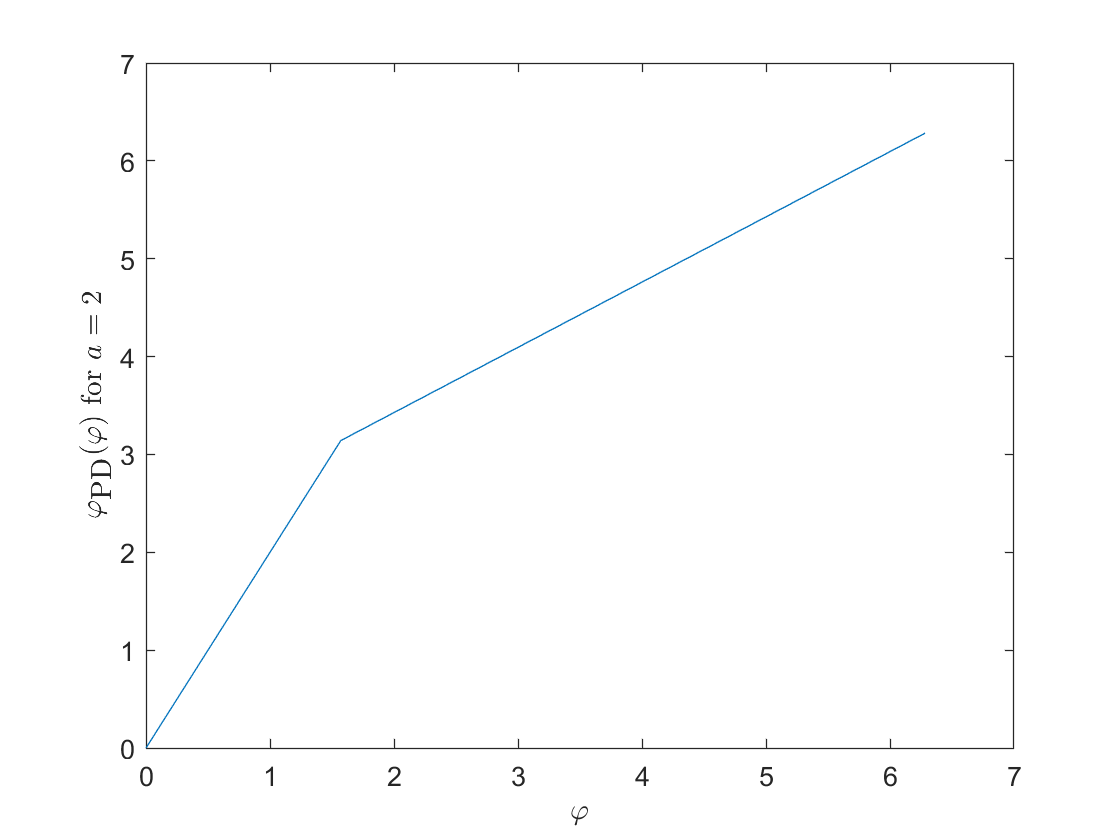

x = 0:0.01*pi:2*pi;
y = PDMcc(x,2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\varphi_{\mbox{PD}}(\varphi)$$ for $$a=2$$','Interpreter','latex');

### 1.2   Modulation Angle Parameter

fprintf('\n1.2 Modulation Angle Parameter');


1.2 Modulation Angle Parameter

The modulation angle parameter $\vartheta$ can be computed from the slope parameter $a$ as follows

    $\vartheta = 180°-\arctan(a)+\arctan(b) = 180°-\arctan(a)+\arctan\left(\frac{a}{2a-1}\right)$.

fprintf('Modulation angle theta as function of slope paramerter a');

Modulation angle theta as function of slope paramerter a

fprintf('- Symbolic solution');

- Symbolic solution

syms theta real;
assume(theta>0 & theta<=pi & a>=1);
eqns = theta==pi-atan(a)+atan(b);
solve(eqns,a);

There seems to be no explicit inverse function (and I do not know it any better). Hence we plot $\vartheta(a)$and compute a lookup table.

fprintf('- Plot');

- Plot

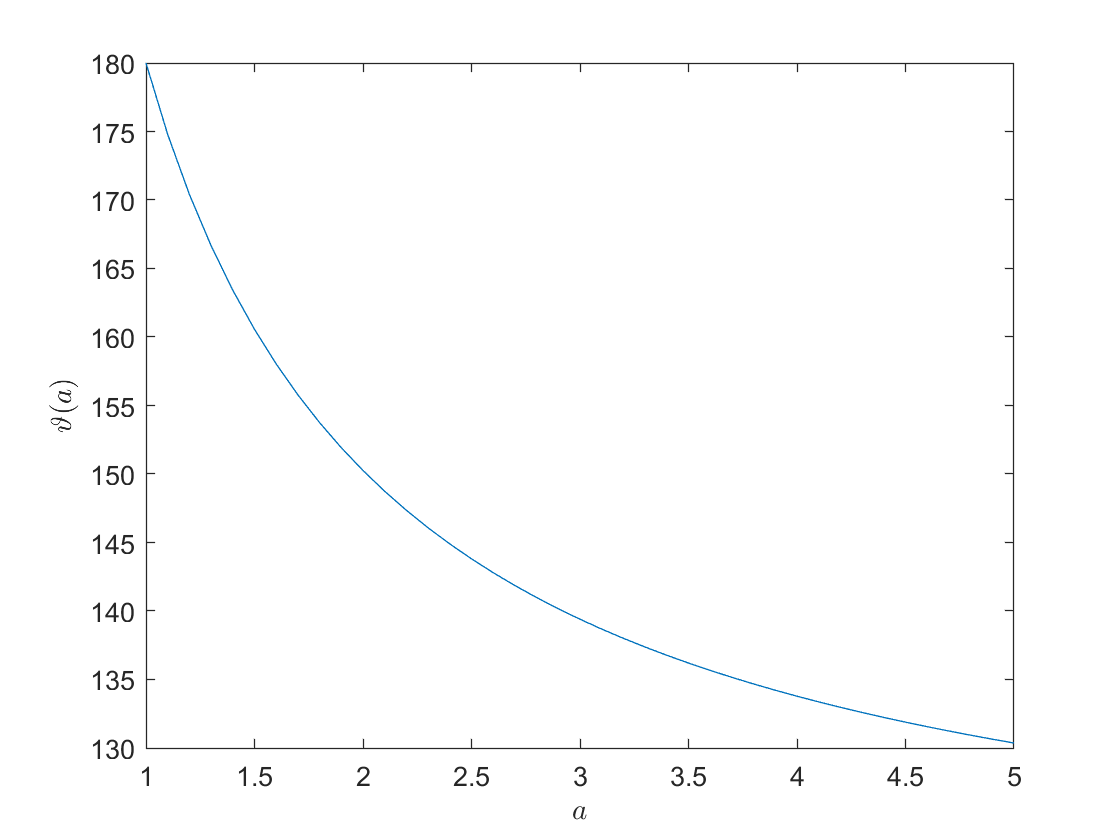

x = 1:0.1:5;
y = a2theta(x);
plot(x,y);
xlabel('$$a$$','Interpreter','latex');
ylabel('$$\vartheta(a)$$','Interpreter','latex');


fprintf('- Lookup table');

- Lookup table

for i=135:5:180
  theta = i/180*pi;
  S = solve(theta==pi-atan(a)+atan(b),a); 
  fprintf('  phi = %d°\n  -> a = %g =',i,eval(S)); disp(S);
end

  phi = 135°
  -> a = 3.73205 =

$$\sqrt{3}+2$$

  phi = 140°
  -> a = 2.92095 =

$$-\frac{\tan\left(\frac{2\,\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{2\,\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{2\,\pi }{9}\right)-2}$$

  phi = 145°
  -> a = 2.3908 =

$$-\frac{\tan\left(\frac{7\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{7\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{7\,\pi }{36}\right)-2}$$

  phi = 150°
  -> a = 2.0162 =

$$-\frac{\sqrt{3}+\sqrt{15}+3}{\sqrt{3}-6}$$

  phi = 155°
  -> a = 1.7371 =

$$-\frac{\tan\left(\frac{5\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{5\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{5\,\pi }{36}\right)-2}$$

  phi = 160°
  -> a = 1.52116 =

$$-\frac{\tan\left(\frac{\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{9}\right)-2}$$

  phi = 165°
  -> a = 1.34946 =

$$\frac{\sqrt{3}\,\left(\sqrt{15-8\,\sqrt{3}}-\sqrt{3}+3\right)}{3}$$

  phi = 170°
  -> a = 1.21017 =

$$-\frac{\tan\left(\frac{\pi }{18}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{18}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{18}\right)-2}$$

  phi = 175°
  -> a = 1.09548 =

$$-\frac{\tan\left(\frac{\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{36}\right)-2}$$

  phi = 180°
  -> a = 1 =

$$1$$

## 2   VZ Wavetable Samples `SINE` and `SAW1` ... `SAW5`

### 2.1   PD-Modulated Sine Waves

fprintf('2.1 PD-Modulated Sine Waves');

2.1 PD-Modulated Sine Waves

We start with one cylcle phase shifted sine wave

    $x(\varphi)=\sin\left(\varphi+\frac{\pi}{2}\right)$.

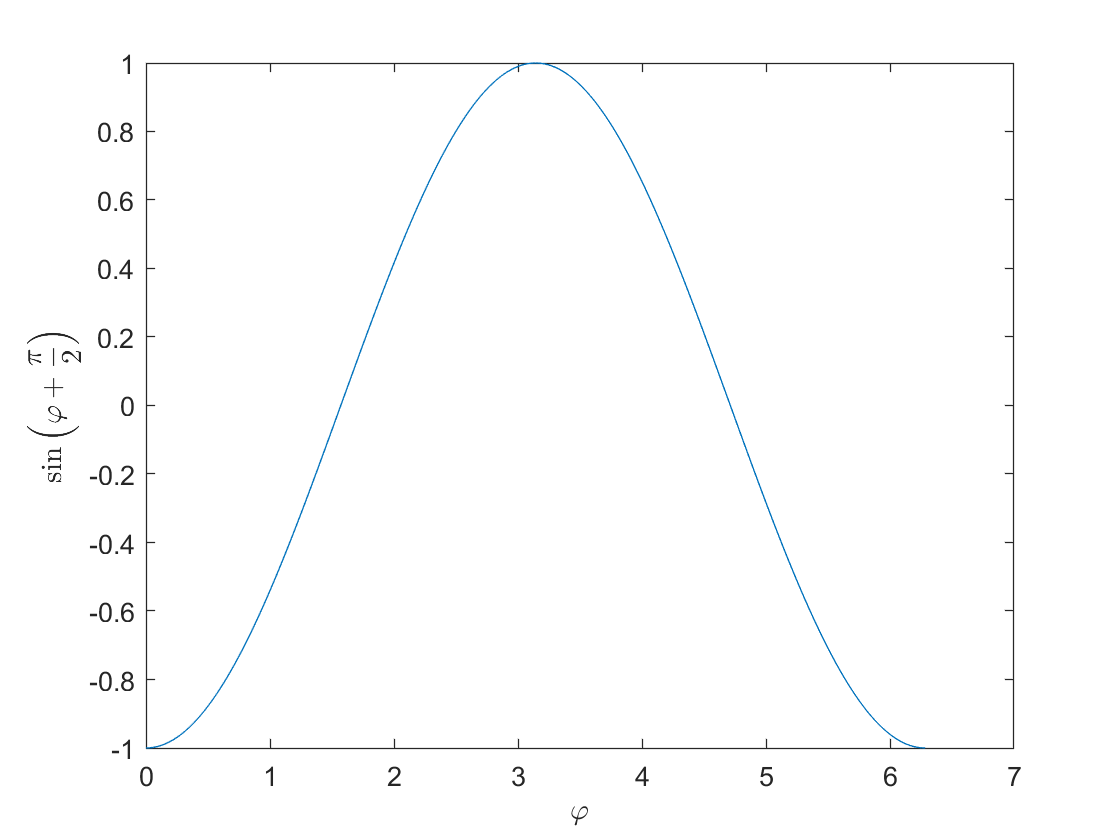

x = 0:0.01*pi:2*pi;
y = sin(x-pi/2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\sin\left(\varphi+\frac{\pi}{2}\right)$$','Interpreter','latex');

PD modulation of that sine wave can be written as

    $x_{\text{PD}}(\varphi) 
= x\big(\varphi_{\text{PD}}(\varphi)\big) 
= \sin\left(\varphi_{\text{PD}}(\varphi)-\frac{\pi}{2}\right)$.

Example for $a=2$:

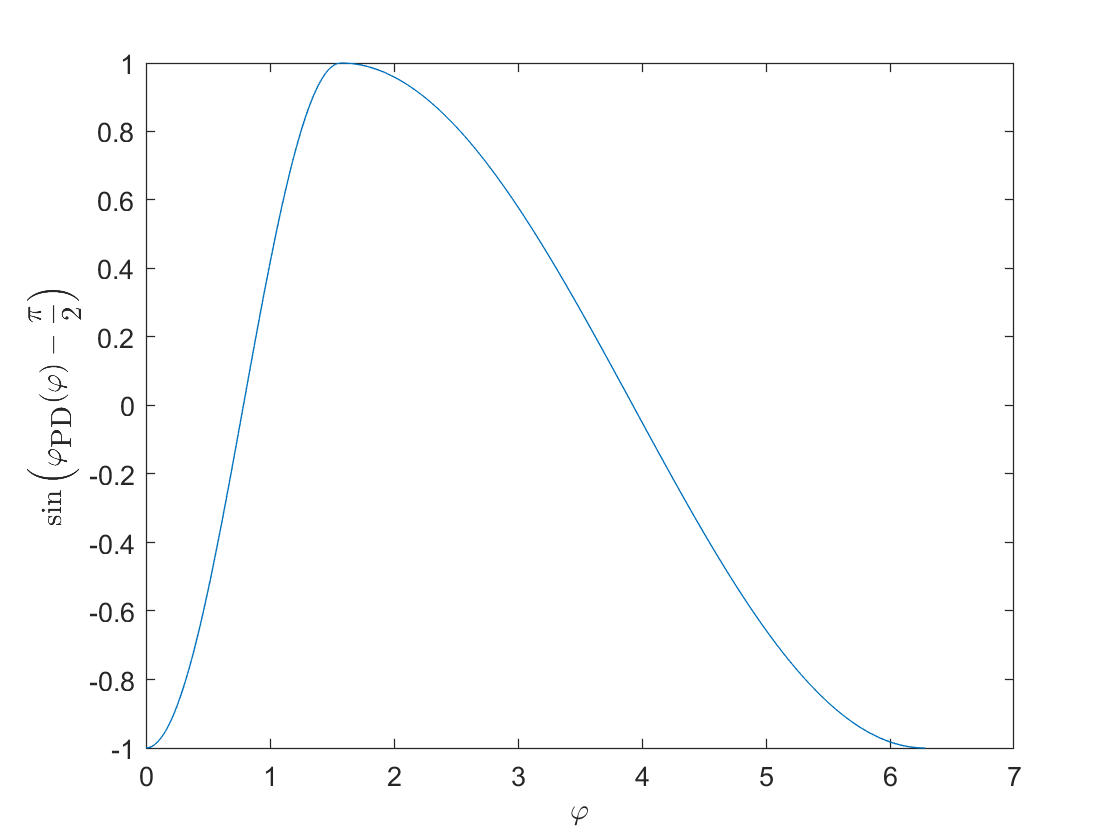

x = 0:0.01*pi:2*pi;
y = sin(PDMcc(x,2)-pi/2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\sin\left(\varphi_{\mbox{PD}}(\varphi)-\frac{\pi}{2}\right)$$','Interpreter','latex');

### 2.2   Creating the Wavetable Samples

fprintf('2.2 Creating the Wavetable Samples');

2.2 Creating the Wavetable Samples

Measuring the original wavetable samples gives the following parameter table:

names  = {'SINE';'SAW1';'SAW2';'SAW3';'SAW4';'SAW5'};
thetas = [180   ;171   ;162   ; 153  ; 144  ; 135  ];
as     = theta2a(thetas); 
T = table(names,thetas,as);
T.Properties.VariableNames = {'Name';'theta';'a'};
fprintf('Overview');

Overview

T

T = 6×3 table
     Name     theta      a   
    ______    _____    ______

    'SINE'     180          1
    'SAW1'     171     1.1855
    'SAW2'     162      1.448
    'SAW3'     153     1.8397
    'SAW4'     144     2.4817
    'SAW5'     135     3.7321


For generating the waves, we use a sampling frequency of 44.1 kHz and a cycle length of 2048 samples. **[TODO: compute frequrncy and pitch!]**

Generating SINE.wav ...


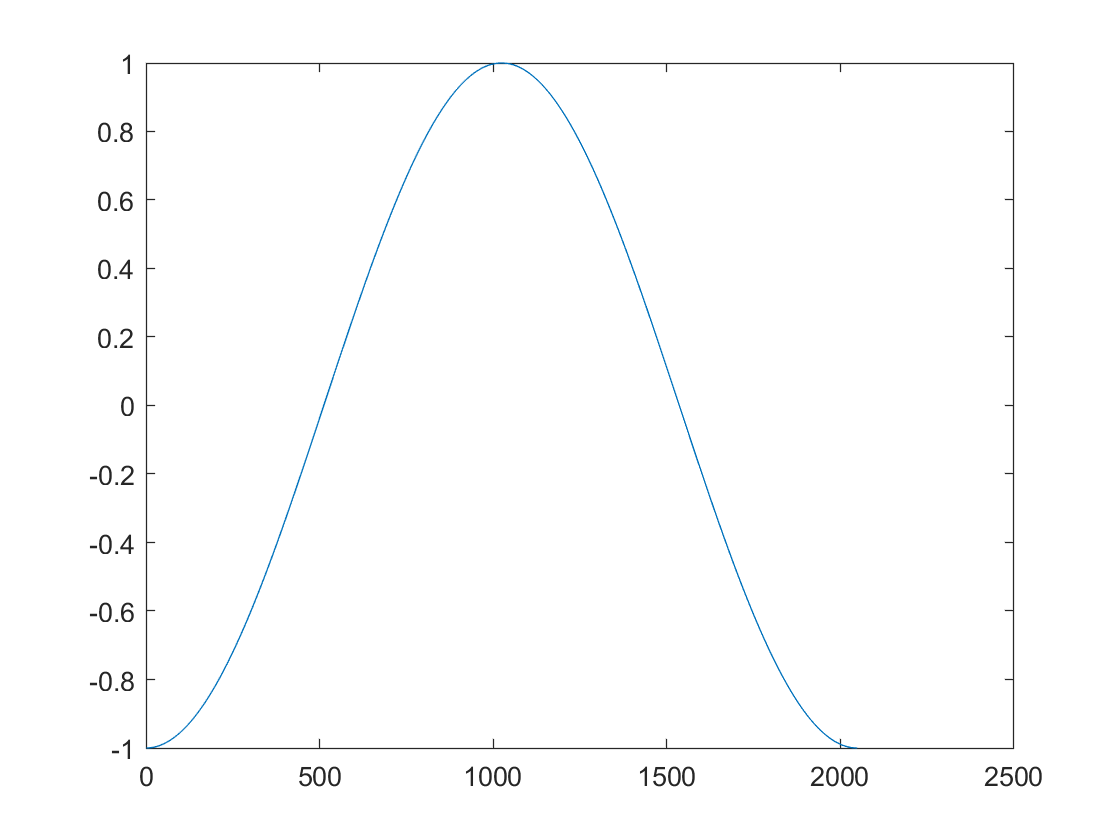

Generating SAW1.wav ...


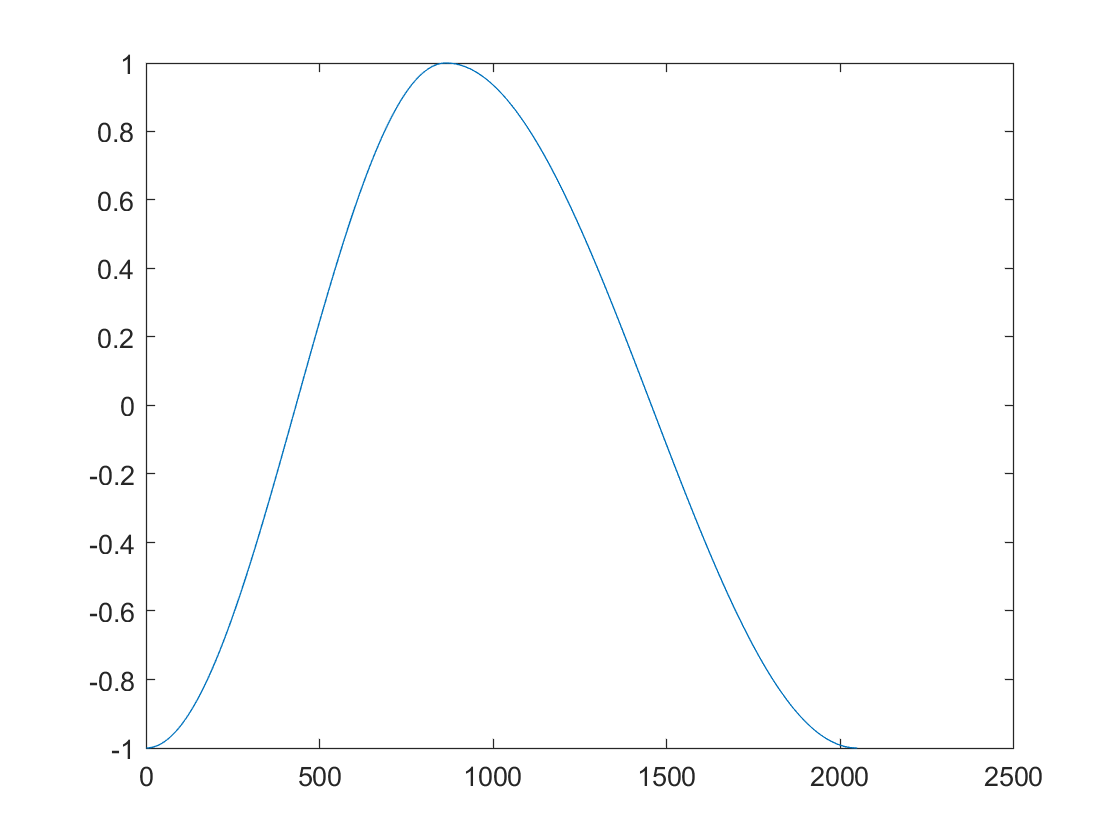

Generating SAW2.wav ...


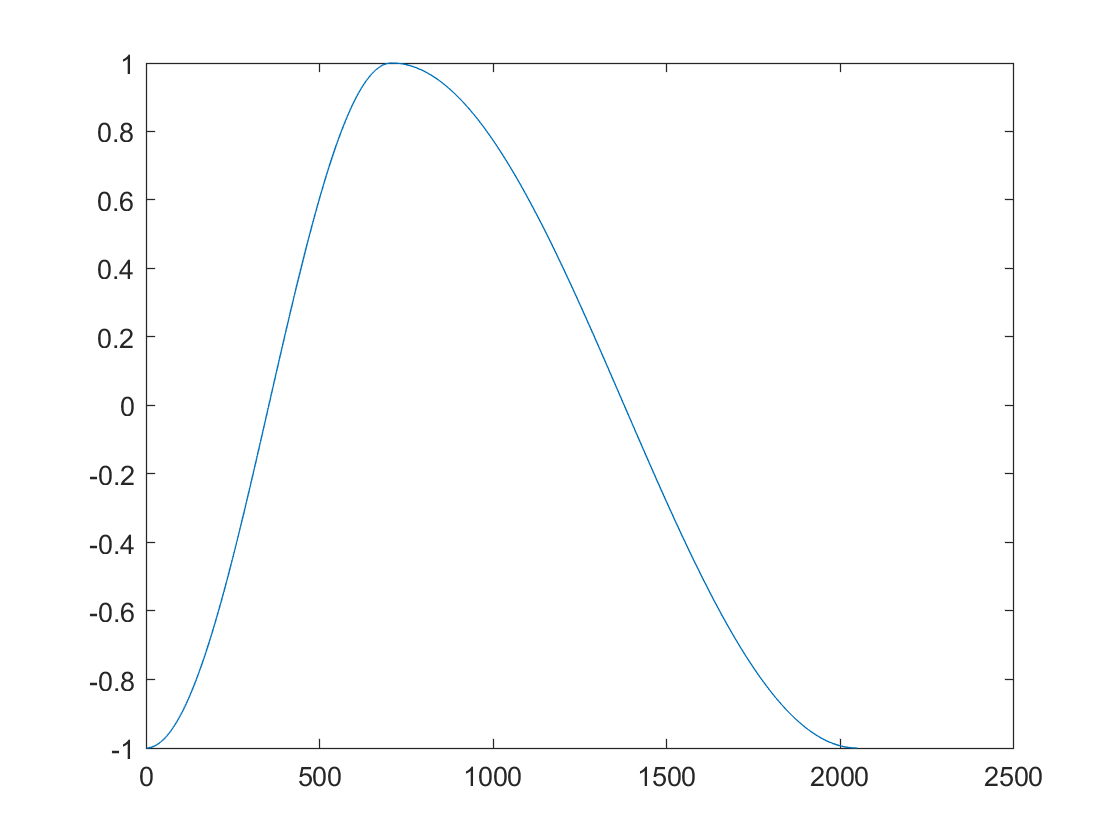

Generating SAW3.wav ...


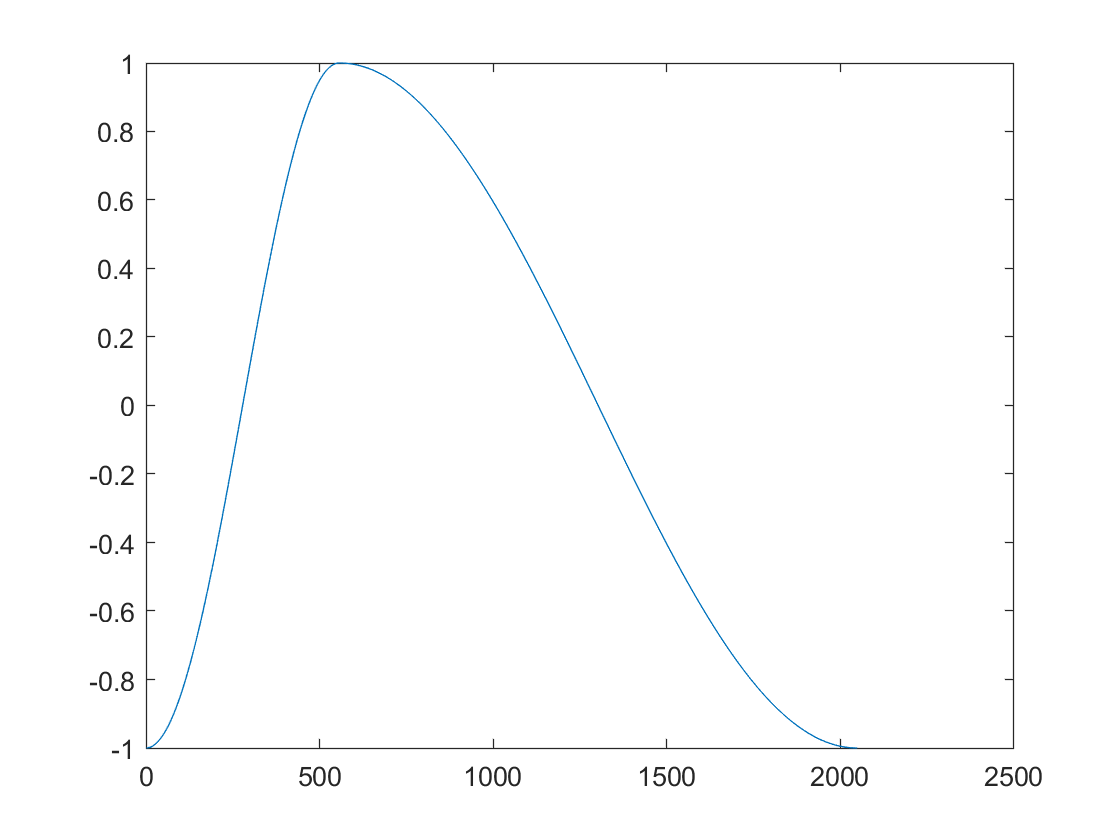

Generating SAW4.wav ...


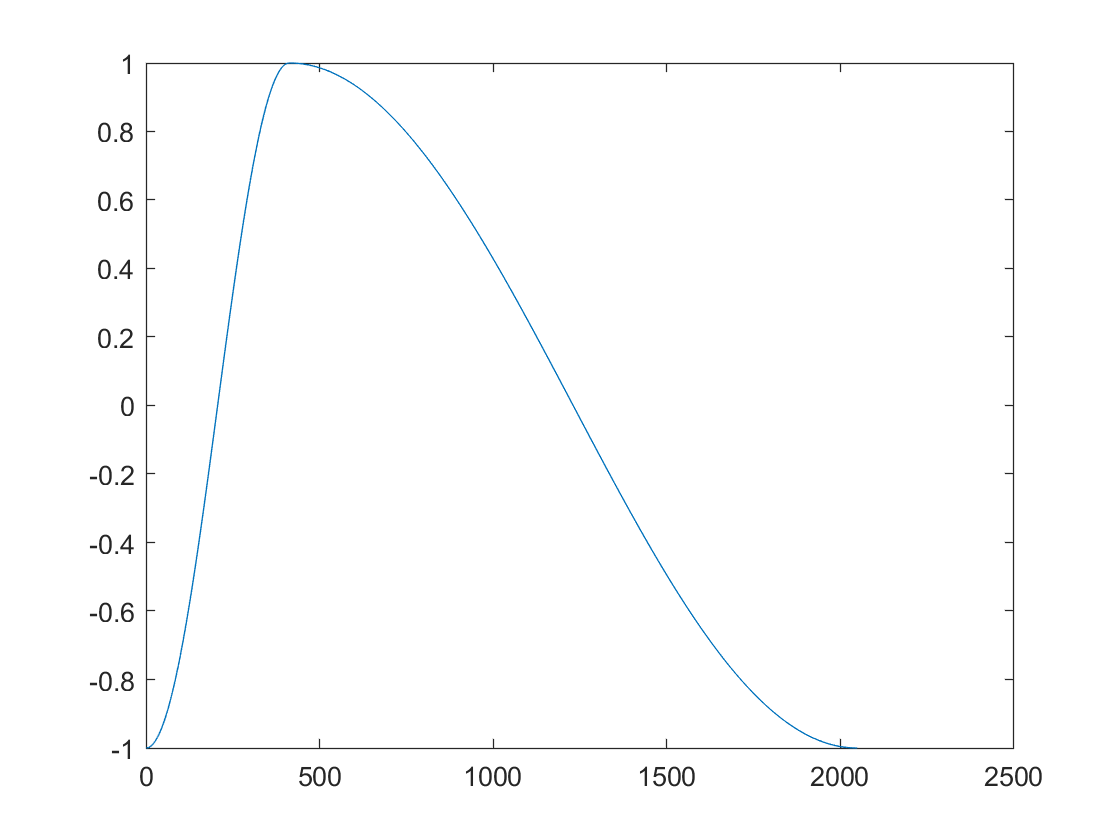

Generating SAW5.wav ...


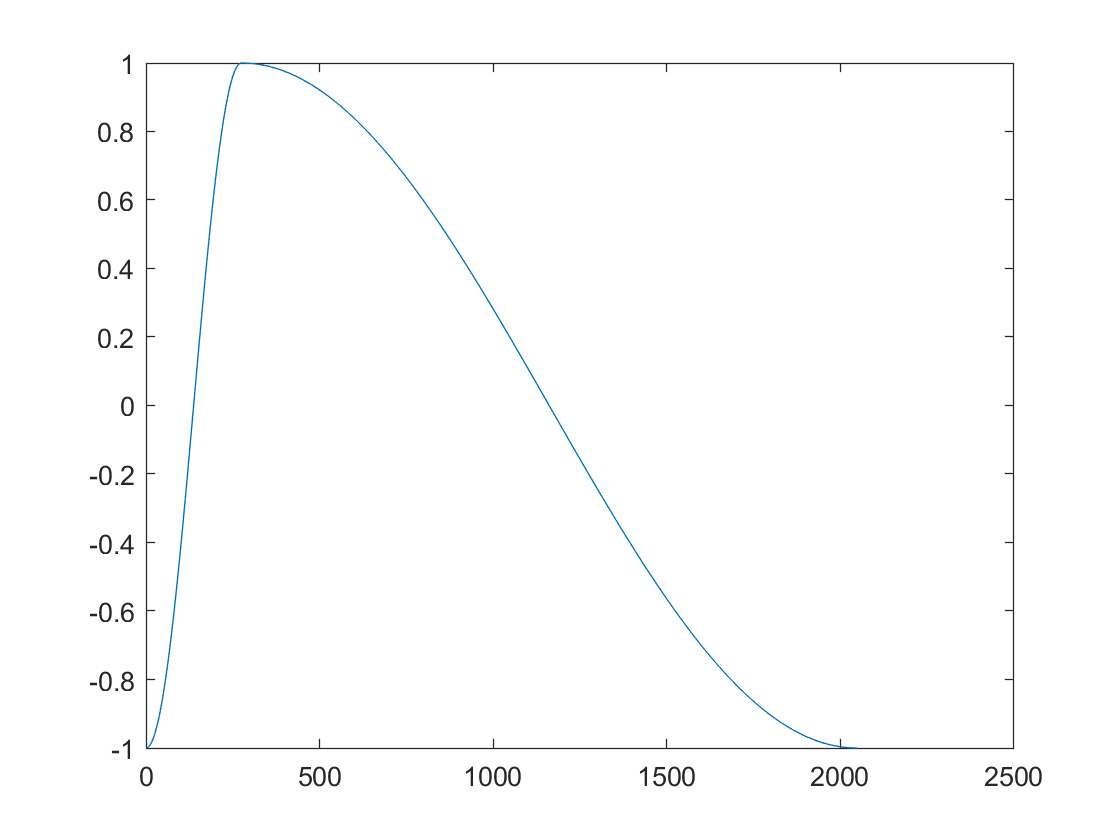

for i=1:length(T.Name)
  fprintf('Generating %s.wav ...\n',T.Name{i});
  k = 1:2048;
  wave = sin(PDMcc(k/2048*2*pi,T.a(i))-pi/2);
  audiowrite(sprintf('../waves/wavetable/%s.wav',T.Name{i}),wave,44100);
  figure; plot(wave);
end

## Appendix A    Local Functions

### A.1   Convert Slope Parameter to Modulation Angle Parameter

function theta = a2theta(a) 
  theta = (pi-atan(a)+atan(a./(2*a-1)))/pi*180;
end

### A.2   Modulation Angle Parameter to Slope Parameter

function aparam = theta2a(theta)
  aparam = theta;
  syms a real;
  assume(a>=1);
  for i=1:length(theta)
    t = theta(i)/180*pi;
    S = solve(t==pi-atan(a)+atan(a/(2*a-1)),a);
    aparam(i) = eval(S);
  end
end

### A.3   Phase Distortion Characteristic Curve

function phipd = PDMcc(phi,a)
  assert(all(phi>=0) && all(phi<=2*pi));
  phi0 = pi./a;
  phipd = (phi<=phi0).*a.*phi + (phi>phi0).*(a.*phi+2*pi*(a-1))/(2*a-1);
end